# **디지털신호처리 ****HW#2**

Due date : 2021.12.22. 23:59

**이름**** : 강동헌**

**학번**** : 201510607**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : **

1. 이산 비주기 신호 $x\left\lbrack n\right\rbrack =\left\lbrace \underset{\uparrow }{1} ,2,2,1\right\rbrace$에 대하여 다음을 구하라.

1) 4점 DFT 및 IDFT를 수행하라. 그리고 DFT의 결과를 DTFT와 비교하라. 

% DFT
xn = [1,2,3,4];
N = 4;
XK = dft(xn,N)

XK =   10.0000 + 0.0000i  -2.0000 + 2.0000i  -2.0000 - 0.0000i  -2.0000 - 2.0000i


realXK = real(XK)

realXK =    10.0000   -2.0000   -2.0000   -2.0000


imagXK = imag(XK)

imagXK =          0    2.0000   -0.0000   -2.0000


% IDFT
XI = ifft(xn,N)

XI =    2.5000 + 0.0000i  -0.5000 - 0.5000i  -0.5000 + 0.0000i  -0.5000 + 0.5000i


realXI = real(XI)

realXI =     2.5000   -0.5000   -0.5000   -0.5000


imagXI = imag(XI)

imagXI =          0   -0.5000         0    0.5000



% DTFF
n = 0:3;
w= 0:300;
XD = xn*exp(-j*n'*w) 

XD =   10.0000 + 0.0000i  -3.1278 - 4.9753i   2.0475 + 1.5695i  -1.7440 - 1.0925i   2.6316 + 0.6918i  -3.9886 + 0.9488i   8.0932 + 5.1725i   0.7271 - 7.6324i  -0.4673 + 2.5073i  -0.0099 - 2.3968i   1.1631 + 2.3013i  -2.0441 - 1.9731i   3.4484 + 7.7570i   5.8222 - 6.9832i  -3.2143 + 0.8722i   2.0447 - 1.7401i  -0.9732 + 1.9945i   0.8726 - 2.3454i  -1.3805 + 6.7125i   9.4421 - 2.9335i  -3.9943 - 2.8420i   2.6482 + 0.4068i  -1.9990 + 0.0708i   2.6114 - 0.5538i  -3.9411 + 3.1006i   9.5643 + 2.6030i  -1.6263 - 6.5409i   1.0345 + 2.2832i  -1.0856 - 1.9099i   2.1404 + 1.6359i  -3.3410 - 0.6855i   6.1197 + 6.8187i   3.1223 - 7.7973i  -1.8662 + 2.0767i   1.0296 - 2.3437i   0.1287 + 2.4168i  -0.6556 - 2.4852i   1.0358 + 7.7007i   7.8612 - 5.4310i  -3.9365 - 0.7107i   2.5917 - 0.8310i  -1.6775 + 1.2172i   1.9359 - 1.6865i  -2.9653 + 5.2078i   9.9922 - 0.3539i  -3.2779 - 4.7373i   2.1509 + 1.4470i  -1.8032 - 0.9641i   2.6630 + 0.5498i  -4.0292 + 1.1915i


realXD = real(XD)

realXD =    10.0000   -3.1278    2.0475   -1.7440    2.6316   -3.9886    8.0932    0.7271   -0.4673   -0.0099    1.1631   -2.0441    3.4484    5.8222   -3.2143    2.0447   -0.9732    0.8726   -1.3805    9.4421   -3.9943    2.6482   -1.9990    2.6114   -3.9411    9.5643   -1.6263    1.0345   -1.0856    2.1404   -3.3410    6.1197    3.1223   -1.8662    1.0296    0.1287   -0.6556    1.0358    7.8612   -3.9365    2.5917   -1.6775    1.9359   -2.9653    9.9922   -3.2779    2.1509   -1.8032    2.6630   -4.0292


imagXD = imag(XD)

imagXD =          0   -4.9753    1.5695   -1.0925    0.6918    0.9488    5.1725   -7.6324    2.5073   -2.3968    2.3013   -1.9731    7.7570   -6.9832    0.8722   -1.7401    1.9945   -2.3454    6.7125   -2.9335   -2.8420    0.4068    0.0708   -0.5538    3.1006    2.6030   -6.5409    2.2832   -1.9099    1.6359   -0.6855    6.8187   -7.7973    2.0767   -2.3437    2.4168   -2.4852    7.7007   -5.4310   -0.7107   -0.8310    1.2172   -1.6865    5.2078   -0.3539   -4.7373    1.4470   -0.9641    0.5498    1.1915


2) 영 채우기를 시행하여 같은 신호에 대해 16점 DFT 및 IDFT를 수행하라.

xnz = [1,2,3,4,0,0,0,0,0,0,0,0,0,0,0,0];
N2 = 16;
XK2 = dft(xn,N)

XK2 =   10.0000 + 0.0000i  -2.0000 + 2.0000i  -2.0000 - 0.0000i  -2.0000 - 2.0000i


realXK2 = real(XK)

realXK2 =    10.0000   -2.0000   -2.0000   -2.0000


imagXK2 = imag(XK)

imagXK2 =          0    2.0000   -0.0000   -2.0000



% IDFT
XI2 = ifft(xn,N)

XI2 =    2.5000 + 0.0000i  -0.5000 - 0.5000i  -0.5000 + 0.0000i  -0.5000 + 0.5000i


realXI2 = real(XI)

realXI2 =     2.5000   -0.5000   -0.5000   -0.5000


imagXI2 = imag(XI)

imagXI2 =          0   -0.5000         0    0.5000


2. (P5.2) DFS의 정의를 사용하여 다음 주기 신호의 DFS 계수를 구하고, MATLAB을 사용하여 검증하라.

1) $\tilde{x_1 } \left(n\right)=\left\lbrace 4,1,-1,1\right\rbrace ,N=4$

Xtilde = Σ(xtilde(n)*j^nk)] , w=j

X(0)tilde = x(0) + x(1) + x(2) + x(3) = 5

X(1)tilde = x(0)*1 + x(1)*w + x(2)*w^2 + x(3)*w^3 =  5 

X(2)tilde =  x(0) - x(1) + x(2) - x(3) = 1

X(3)tilde = x(0)*1 + x(1)*w^3 + x(2)*w^6 + x(3)*w^9 = 5

x1tilde = [4,1,-1,1];
N1 = 4;
X1tilde = dfs(x1tilde,N1)

X1tilde =    5.0000 + 0.0000i   5.0000 + 0.0000i   1.0000 - 0.0000i   5.0000 + 0.0000i


2) $\tilde{x_2 } \left(n\right)=\left\lbrace 1,0,-1,-1,0\right\rbrace ,N=5$

Xtilde = Σ(xtilde(n)*j^nk)] , w = exp(-j*2*pi/5) =  0.309 + 0.9511j

X(0)tilde = x(0) + x(1) + x(2) + x(3) + x(4) = -1

X(1)tilde = x(0)*1 + x(1)*w + x(2)*w^2 + x(3)*w^3  + x(4)*w^4

X(2)tilde =  x(0)*1 + x(1)*w^2 + x(2)*w^4 + x(3)*w^6  + x(4)*w^8

X(3)tilde = x(0)*1 + x(1)*w^3 + x(2)*w^6 + x(3)*w^9  + x(4)*w^12

X(4)tilde =  x(0)*1 + x(1)*w^4 + x(2)*w^8 + x(3)*w^12  + x(4)*w^16

x2tilde = [1,0,-1,-1,0];
N2 = 5;
X2tilde = dfs(x2tilde,N2)

X2tilde =   -1.0000 + 0.0000i   2.6180 + 0.0000i   0.3820 - 0.0000i   0.3820 + 0.0000i   2.6180 + 0.0000i


3.  (P5.10) 아래와 같이 주어진 유한 길이 신호를 고려하자.


$$x\left(n\right)=\left\lbrace \begin{array}{ll}
{\mathrm{sinc}}^2 \left\lbrace \frac{\left(n-50\right)}{2}\right\rbrace  & 0\le n\le 100\\
0 & \mathrm{otherwise}
\end{array}\right.$$


1) x(n)의 DFT X(k)를 구하라. (stem 함수를 사용하여) 그것의 크기 및 위상 그래프를 그려라. 

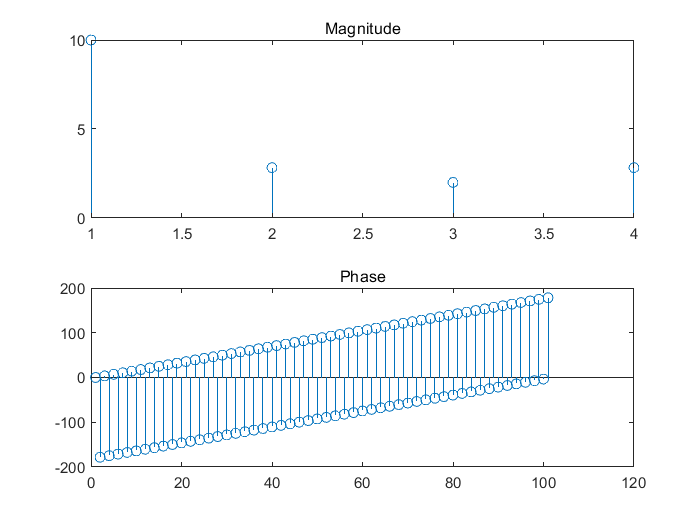

% DFT
n = 0:100;
xn = sinc((n-50)/2).^2;
N = 101;
Xk = dft(xn,N);
magXk = abs(XK);
phaseXk = angle(Xk)*180/pi;
subplot(2,1,1); stem(magXk); title('Magnitude');
subplot(2,1,2); stem(phaseXk); title('Phase');

2) MATLAB을 사용하여 x(n)의 DTFT $X\left(e^{j\omega } \right)$의 크기 및 위상 그래프를 그려라.

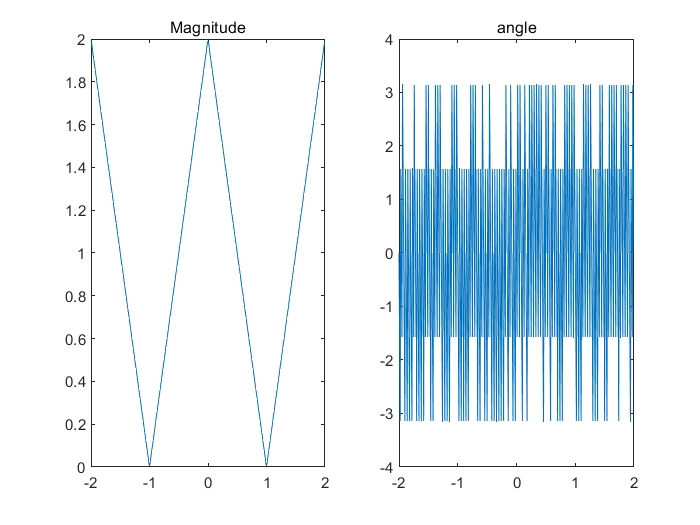

%DTFT
k = -200:200;
w = (pi/100)*k;
X = xn*exp(-j*n'*w);

magX = abs(X);
phaseX = angle(X);
subplot(1,2,1);
plot(w/pi,magX); title('Magnitude');
subplot(1,2,2); title('Phase');
plot(w/pi,phaseX); title('angle');

3) 위 DFT는 $X\left(e^{j\omega } \right)$의 샘플링된 변형임을 검증하라. hold 함수 (hold on;) 를 사용해서 두 그래프를 합치도록 한다.

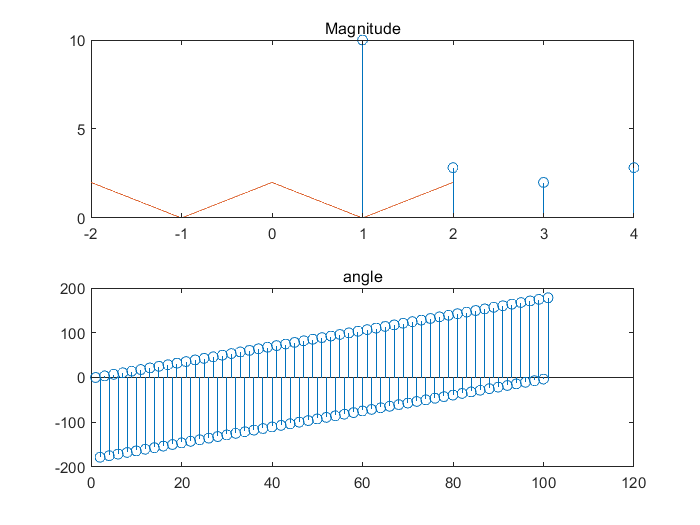


subplot(2,1,1); stem(magXk); title('Magnitude'); hold on
subplot(2,1,2); stem(phaseXk); title('Phase'); hold on

subplot(2,1,1);
plot(w/pi,magX); title('Magnitude');  hold off
subplot(2,1,2); title('Phase');
plot(100,phaseX); title('angle');  hold off

4) DFT $X\left(k\right)$로부터 DTFT $X\left(e^{j\omega } \right)$를 재구성할 수 있는가? 가능하다면, 재구성에 필요한 보간 공식을 구하라. 가능하지 않다면, 그 이유를 기술하라.

재구성 가능. 

x${\left(e\right.}^{\mathrm{jw}}$) = $\;\sum_{k=0}^{N-1} \overset{~}{X} \left(k\right)\frac{1-e^{-\mathrm{jwN}} }{1-e^{\mathrm{j2}\pi \frac{k}{N}} e^{-\mathrm{jw}} }$ =  $\;\sum_{k=0}^{N-1} \overset{~}{X} \left(k\right)\phi \left(w-\frac{2\pi k}{N}\right)$ [ $\phi \left(w\right)\approx \frac{\mathrm{sin}\left(\frac{\mathrm{wN}}{2}\right)}{\mathrm{Nsin}\left(\frac{w}{2}\right)}e^{-\mathrm{jw}\left(\frac{N-1}{2}\right)}$ : 보간 다항식

function [Xk] = dft(xn,N)
n = [0:1:N-1];
k =  [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN.^nk;
Xk = xn*WNnk;

end

function [Xk] = dfs(xn,N) % DFS Function

n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN.^nk;
Xk = xn*WNnk;
end
